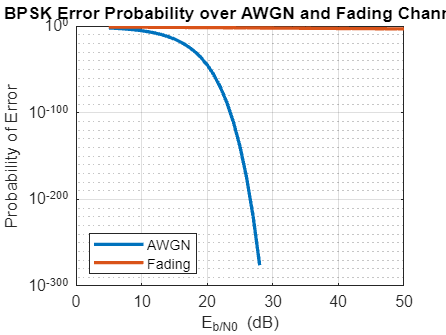

clear;

% Set Our Eb/No Bounds
EbNo_dB = 5:1:50;
EbNo = 10.^(EbNo_dB/10);

% Probability of error for BPSK over AWGN
Pe_bpsk_awgn = qfunc(sqrt(2*EbNo));

% Average probability of error over fading channel
Pe_avg_bpsk_fad = zeros(size(EbNo));

% Compute The Integral
for k = 1:length(EbNo)
    gamma = EbNo(k);
    integrand = @(a) 0.5 * qfunc(a .* sqrt(2*gamma));
    Pe_avg_bpsk_fad(k) = integral(integrand, 0, 2);
end

% Plot
figure;
semilogy(EbNo_dB, Pe_bpsk_awgn, 'LineWidth', 2); 
hold on;
semilogy(EbNo_dB, Pe_avg_bpsk_fad, 'LineWidth', 2);

grid on;
xlabel('E_b/N_0 (dB)');
ylabel('Probability of Error');
title('BPSK Error Probability over AWGN and Fading Channels');
legend('AWGN', 'Fading', 'Location', 'southwest');
hold off;

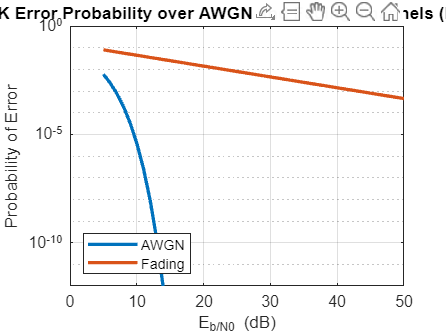


% Plot with range limit
figure;
semilogy(EbNo_dB, Pe_bpsk_awgn, 'LineWidth', 2); 
hold on;
semilogy(EbNo_dB, Pe_avg_bpsk_fad, 'LineWidth', 2);

grid on;
xlabel('E_b/N_0 (dB)');
ylabel('Probability of Error');
title('BPSK Error Probability over AWGN and Fading Channels (Limited)');
legend('AWGN', 'Fading', 'Location', 'southwest');
hold off;
ylim([1e-12 1]);

% Pe
Pe = 1e-3;

% AWGN Eb/N0 for given Pe
EbNo_awgn_dB = 10*log10((qfuncinv(Pe))^2/2);

% FADING Eb/N0 for given Pe
idx = find(Pe_avg_bpsk_fad <= Pe, 1);
EbNo_fading_dB = EbNo_dB(idx);

% Fade margin
fade_margin_dB = EbNo_fading_dB - EbNo_awgn_dB;

% Print out values
fprintf('Eb/N0 (AWGN) = %f dB\n', EbNo_awgn_dB);

Eb/N0 (AWGN) = 6.789523 dB


fprintf('Eb/N0 (Fading) = %f dB\n', EbNo_fading_dB);

Eb/N0 (Fading) = 43.000000 dB


fprintf('Fade Margin = %f dB\n', fade_margin_dB);

Fade Margin = 36.210477 dB
